# **기계제어공학부 기전융합종합설계 **

#### **Patient-Friendly Falling Suspicion Alarm System Based on 3D Bounding Box on 3D LiDAR Point Cloud**

Name:        Hong Se Hyun

Date:          2022.12.02.

# **1. Add Path/Library**

**Start Project**

clc;     clear all;     close all

addpath(genpath('config'))
addpath(genpath('eval'))
addpath(genpath('models'))
addpath(genpath('utils'))

warning ('off','all');

# **2-1.   Load Train Data**

**Get ground truth label information.**

[matFiles, numFiles, mydata] = DataProcess_LoadData('traindata');

mydata_path = "../data/traindata/labeling_NTH214_1025_2030_JIHYUNBIN.mat"

mydata_path = "../data/traindata/labeling_NTH214_1025_2045_HANKWANGYONG.mat"

mydata_path = "../data/traindata/labeling_NTH214_1025_2115_ANCHANGMIN.mat"

mydata_path = "../data/traindata/labeling_NTH214_1025_2120_LEEHAEUN.mat"

mydata_path = "../data/traindata/labeling_NTH214_1028_1945_HUDABIN.mat"

mydata_path = "../data/traindata/labeling_NTH214_1028_2000_KIMHAEUN.mat"

mydata_path = "../data/traindata/labeling_NTH214_1028_2045_HONGSEHYUN.mat"

mydata_path = "../data/traindata/labeling_NTH214_1028_2100_YANGJIWOO.mat"

mydata_path = "../data/traindata/labeling_NTH214_1028_2115_CHOIYOONSEOK.mat"

mydata_path = "../data/traindata/labeling_NTH214_1028_2130_ANGYEONHEAL.mat"

# **2-2.   Data Pre-processing**

Get bounding boxes coordinate values

**10  frame = 1  second**

'pcap File to pcd File' Processed Frames = **0100~1300 **Frames

**→** Number of frames in pcd file format = **1201** **(=0100~1300)**

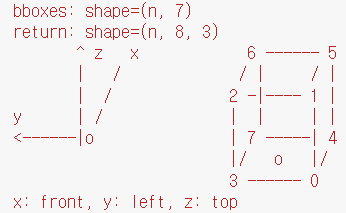

**Get names & Setting Base Variables**

mode = 2;

train_frame_info = DataProcess_DefineTrainFrames(numFiles, matFiles, mode)

train_frame_info = 다음 필드를 포함한 1×10 struct 배열:
    name
    human_detected
    lying_detected


**Get Labeled Frames**

LABEL_human_detected = {};
LABEL_lying_detected = {};

for itr = 1 : numFiles
    [TMP_LABEL_human_detected, TMP_LABEL_lying_detected] = DataProcess_GetLabel_2(mydata{itr,1}, train_frame_info(itr).human_detected, train_frame_info(itr).lying_detected);
    
    LABEL_human_detected = [LABEL_human_detected ; TMP_LABEL_human_detected];
    LABEL_lying_detected = [LABEL_lying_detected ; TMP_LABEL_lying_detected];
end

**Check missing and outliers**

[no_human_detected_label_idx, double_human_detected_label_idx, num_of_human_detecteding]  = DataProcess_DataCheck(LABEL_human_detected);
[no_lying_detected_label_idx, double_lying_detected_label_idx, num_of_lying_detectedting] = DataProcess_DataCheck(LABEL_lying_detected);

# **2-3.   Feature Extraction**

Get bounding boxes' features.

### **Features**

**Feature(1)** : x, y축의 길이의 비율

**Feature(2) **: y, z축의 길이의 비율

**Feature(3) **: z, x축의 길이의 비율 

**Feature(4) **: 3D Bbox에 대한 대각선과 x, y평면이 이루는 각도

**Get Bbox Coordinates**

human_detected_bboxes_coordinates = DataProcess_BboxesExtraction(num_of_human_detecteding,  LABEL_human_detected);
lying_detected_bboxes_coordinates = DataProcess_BboxesExtraction(num_of_lying_detectedting, LABEL_lying_detected);

**Feature Extraction**

human_detected_feature_table = DataProcess_FeatureExtraction(human_detected_bboxes_coordinates);
lying_detected_feature_table = DataProcess_FeatureExtraction(lying_detected_bboxes_coordinates);

# **2-4.   Data Post-processing**

**Add ground truth label to feature table**

human_detected_feature_label_table = DataProcess_AddLabel(human_detected_feature_table, 'human_detected');
lying_detected_feature_label_table = DataProcess_AddLabel(lying_detected_feature_table, 'lying_detected');

**Define train data table (this table goes to ML)**

column_size = size(human_detected_feature_label_table, 2);

TrainData_Table = [human_detected_feature_label_table(:,1:column_size-1) ; lying_detected_feature_label_table(:,1:column_size-1)]

TrainData_Table = 10000×4 table
    length_ratio_xy    length_ratio_yz    length_ratio_zx    angle_diagonal_line
    _______________    _______________    _______________    ___________________

        0.71343            0.52473            2.6713               57.195       
        0.72334            0.50933            2.7143               57.846       
        0.73347            0.49451             2.757               58.481       
        0.74381            0.48023            2.7995               59.099       
        0.75438            0.46648            2.8417               59.701       
        0.78375            0.45662            2.7942                59.88       
        0.81447            0.44675            2.7483                60.05       
        0.84664            0.43686            2.7037               60.213       
        0.88035            0.42695            2.6605               60.367       
        0.84088            0.44329            2.6827               59.921   

TrainData_Label_Table = [human_detected_feature_label_table(:,column_size) ; lying_detected_feature_label_table(:,column_size)]

TrainData_Label_Table = 10000×1 table
         label      
    ________________

    "human_detected"
    "human_detected"
    "human_detected"
    "human_detected"
    "human_detected"
    "human_detected"
    "human_detected"
    "human_detected"
    "human_detected"
    "human_detected"
    "human_detected"
    "human_detected"
    "human_detected"
    "human_detected"
    "human_detected"
    "human_detected"


# **2-5.   Data Normalizaiton**

**method(1)**

Apply Data Normalization.

TrainData_Table = normalize(TrainData_Table)

TrainData_Table = 10000×4 table
    length_ratio_xy    length_ratio_yz    length_ratio_zx    angle_diagonal_line
    _______________    _______________    _______________    ___________________

        -0.3795            -1.1723            1.3185               1.2875       
       -0.36849            -1.1983             1.368               1.3264       
       -0.35725            -1.2233            1.4171               1.3644       
       -0.34577            -1.2474            1.4659               1.4013       
       -0.33404            -1.2707            1.5144               1.4373       
       -0.30143            -1.2873            1.4599                1.448       
       -0.26733             -1.304             1.407               1.4582       
       -0.23162            -1.3207            1.3558               1.4679       
       -0.19419            -1.3374            1.3061               1.4772       
       -0.23801            -1.3098            1.3316               1.4505   

**method(2)**

Change Data Size by Apply Degree to Radian.

% TrainData_array      = table2array(TrainData_Table);
% TrainData_array(:,4) = TrainData_array(:,4)*pi/180;
% FeatureColumnIndex   = ["length_ratio_xy", "length_ratio_yz", "length_ratio_zx", "angle_diagonal_line"];
% TrainData_Table      = array2table(TrainData_array, 'VariableNames',string(FeatureColumnIndex))

# **2-6.   Supervise Learning**

Train and Evaluate.

**ML - KNN**

Knn_Train_Loss = 1.0000e-04

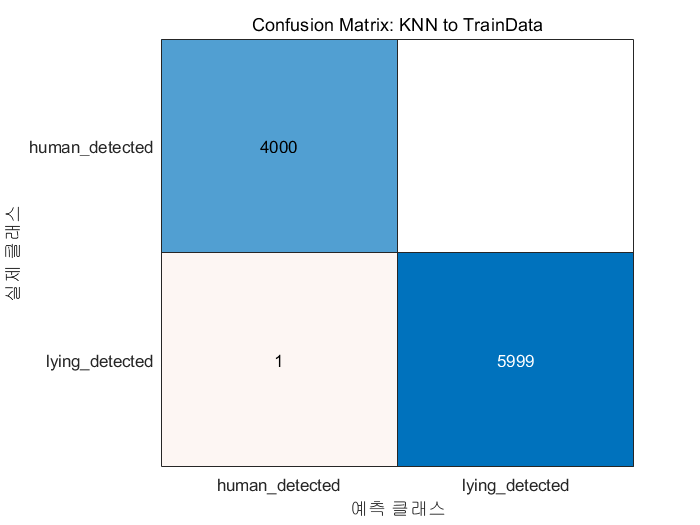

[Knn_Mdl, Knn_Train_Loss, ~] = ML_KnnTrain(TrainData_Table, TrainData_Label_Table, 2);

**ML - SVM**

SVM_Train_Loss = 1.0000e-04

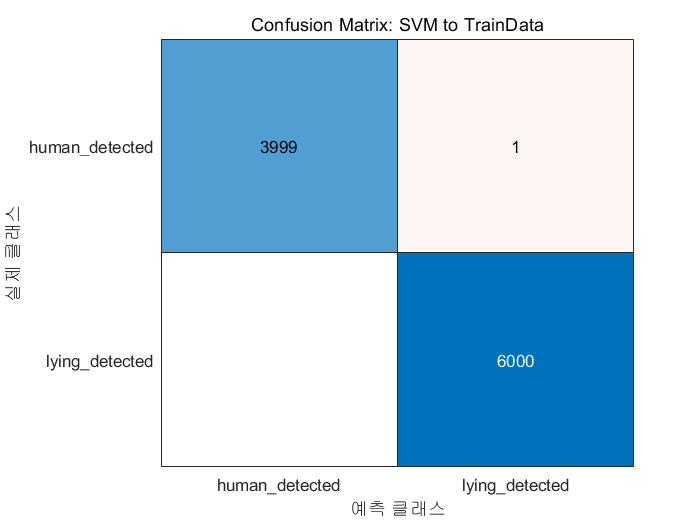

[SVM_Mdl, SVM_Train_Loss, ~] = ML_SVMTrain(TrainData_Table, TrainData_Label_Table);

**ML - TREE**

Tree_Train_Loss = 1.0000e-04

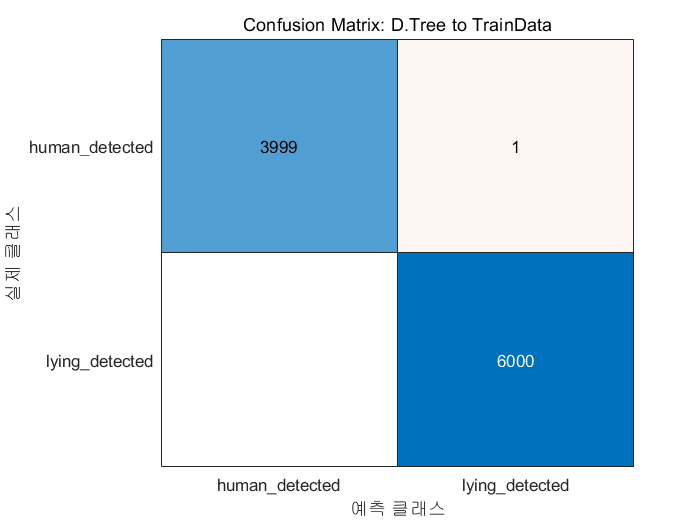

[Tree_Mdl, Tree_Train_Loss, ~] = ML_TreeTrain(TrainData_Table, TrainData_Label_Table);

**ML - Ensemble Method (Random Forest + Bagging)**

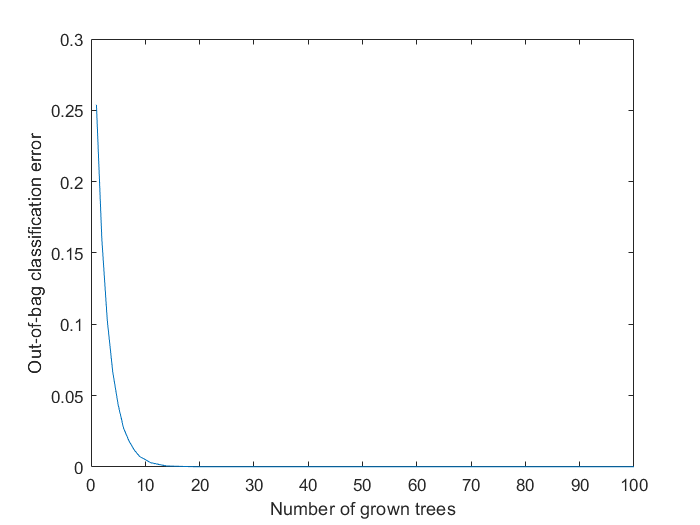

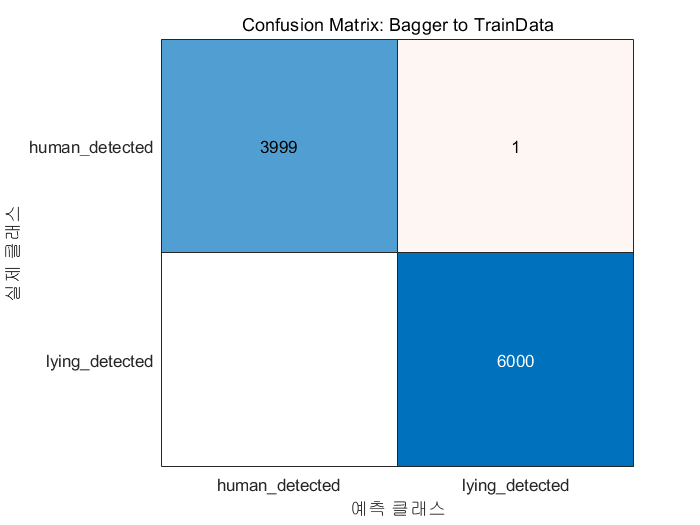

Bagger_Mdl =   TreeBagger
100개 배깅 결정 트리를 사용한 앙상블:
                    Training X:            [10000x4]
                    Training Y:            [10000x1]
                        Method:       classification
                 NumPredictors:                    4
         NumPredictorsToSample:                    2
                   MinLeafSize:                    1
                 InBagFraction:                    1
         SampleWithReplacement:                    1
          ComputeOOBPrediction:                    1
 ComputeOOBPredictorImportance:                    0
                     Proximity:                   []
                    ClassNames: 'human_detected' 'lying_detected'

  Properties, Methods


Ensemble_Train_Loss = 1.0000e-04

[Bagger_Mdl, Ensemble_Train_Loss, ~, ~, ~, ~] = Ensemble_TreeBaggerTrain(TrainData_Table, TrainData_Label_Table)

# **2-7.   Model Save**

save config/trained_Knn_Mdl Knn_Mdl
save config/trained_SVM_Mdl SVM_Mdl
save config/trained_Tree_Mdl Tree_Mdl
save config/trained_Bagger_Forest_Mdl Bagger_Mdl

# **3-1.   Load Test Data**

**Get ground truth label information.**

[matFiles, numFiles, mydata] = DataProcess_LoadData('testdata');

mydata_path = "../data/testdata/labeling_NTH214_1025_1930_CHOIHAEUN.mat"

mydata_path = "../data/testdata/labeling_NTH214_1025_2000_PARKJUEUN.mat"

# **3-2.   Data Pre-processing**

**Get names & Setting Base Variables**

mode = 2;

test_frame_info = DataProcess_DefineTestFrames(numFiles, matFiles, mode)

test_frame_info = 다음 필드를 포함한 1×2 struct 배열:
    name
    human_detected
    lying_detected


**Get Labeled Frames**

LABEL_human_detected = {};
LABEL_lying_detected = {};

for itr = 1 : numFiles
    [TMP_LABEL_human_detected, TMP_LABEL_lying_detected] = DataProcess_GetLabel_2(mydata{itr,1}, test_frame_info(itr).human_detected, test_frame_info(itr).lying_detected);
    
    LABEL_human_detected = [LABEL_human_detected ; TMP_LABEL_human_detected];
    LABEL_lying_detected = [LABEL_lying_detected ; TMP_LABEL_lying_detected];
end

**Check missing and outliers**

[no_human_detected_label_idx, double_human_detected_label_idx, num_of_human_detecting] = DataProcess_DataCheck(LABEL_human_detected);
[no_lying_detected_label_idx, double_lying_detected_label_idx, num_of_lying_detecting] = DataProcess_DataCheck(LABEL_lying_detected);

# **3-3.   Feature Extraction**

**Get Bbox Coordinates**

human_detected_bboxes_coordinates = DataProcess_BboxesExtraction(num_of_human_detecting, LABEL_human_detected);
lying_detected_bboxes_coordinates = DataProcess_BboxesExtraction(num_of_lying_detecting, LABEL_lying_detected);
GT_LABEL = [LABEL_human_detected ; LABEL_lying_detected];

**Feature Extraction**

human_detected_feature_table = DataProcess_FeatureExtraction(human_detected_bboxes_coordinates);
lying_detected_feature_table = DataProcess_FeatureExtraction(lying_detected_bboxes_coordinates);

# **3-4.   Data Post-processing**

**Add ground truth label to feature table**

human_detected_feature_label_table = DataProcess_AddLabel(human_detected_feature_table, 'human_detected');
lying_detected_feature_label_table = DataProcess_AddLabel(lying_detected_feature_table, 'lying_detected');

**Define train data table (this table goes to ML)**

column_size = size(human_detected_feature_label_table, 2);

TestData_Table = [human_detected_feature_label_table(:,1:column_size-1) ; lying_detected_feature_label_table(:,1:column_size-1)]

TestData_Table = 2000×4 table
    length_ratio_xy    length_ratio_yz    length_ratio_zx    angle_diagonal_line
    _______________    _______________    _______________    ___________________

        0.92032            0.51441            2.1123               55.043       
        0.90757            0.51729              2.13               55.063       
        0.89516            0.52013            2.1478               55.082       
        0.88309            0.52292            2.1655               55.099       
        0.84876            0.52981            2.2238               55.204       
        0.81469            0.53682            2.2865                 55.3       
        0.78085            0.54397            2.3543               55.388       
        0.85708            0.52026            2.2426               55.581       
        0.94064            0.49653            2.1411               55.718       
         1.0327            0.47279            2.0482               55.799     

TestData_Label_Table = [human_detected_feature_label_table(:,column_size) ; lying_detected_feature_label_table(:,column_size)]

TestData_Label_Table = 2000×1 table
         label      
    ________________

    "human_detected"
    "human_detected"
    "human_detected"
    "human_detected"
    "human_detected"
    "human_detected"
    "human_detected"
    "human_detected"
    "human_detected"
    "human_detected"
    "human_detected"
    "human_detected"
    "human_detected"
    "human_detected"
    "human_detected"
    "human_detected"


# **3-5.   Data Normalizaiton**

**method(1)**

Apply Data Normalization.

TestData_Table = normalize(TestData_Table)

TestData_Table = 2000×4 table
    length_ratio_xy    length_ratio_yz    length_ratio_zx    angle_diagonal_line
    _______________    _______________    _______________    ___________________

        -0.20816           -1.1858            0.54855               1.0385      
        -0.22164           -1.1791            0.56936               1.0398      
        -0.23474           -1.1724            0.59017                1.041      
         -0.2475           -1.1659            0.61098                1.042      
        -0.28376           -1.1497            0.67939               1.0486      
        -0.31976           -1.1332            0.75301               1.0547      
        -0.35551           -1.1165            0.83246               1.0601      
        -0.27497           -1.1721            0.70148               1.0723      
        -0.18669           -1.2278            0.58229               1.0809      
       -0.089485           -1.2835            0.47337               1.0859    

**method(2)**

Change Data Size by Apply Degree to Radian.

% TestData_array       = table2array(TestData_Table);
% TestData_array(:,4)  = TestData_array(:,4)*pi/180;
% FeatureColumnIndex   = ["length_ratio_xy", "length_ratio_yz", "length_ratio_zx", "angle_diagonal_line"];
% TestData_Table       = array2table(TestData_array, 'VariableNames',string(FeatureColumnIndex))

# **3-6.   Test Pretrained Model**

Knn                     = load('config/20221201_label_2/trained_Knn_Mdl.mat');
SVM                     = load('config/20221201_label_2/trained_SVM_Mdl.mat');
Decision_Tree           = load('config/20221201_label_2/trained_Tree_Mdl.mat');
Ensemble_Bagging_Forest = load('config/20221201_label_2/trained_Bagger_Forest_Mdl.mat');

**ML - KNN**

Test_Loss = 0

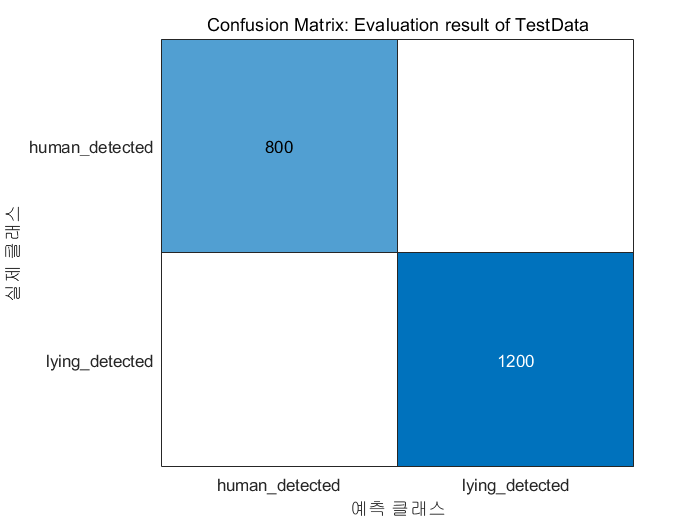

[Knn_Test_Loss, cm_knn] = ML_TEST(Knn.Knn_Mdl, TestData_Table, TestData_Label_Table);

**ML - SVM**

Test_Loss = 0

[SVM_Test_Loss, cm_svm] = ML_TEST(SVM.SVM_Mdl, TestData_Table, TestData_Label_Table);

**ML - Tree**

Test_Loss = 0

[Tree_Test_Loss, cm_tree] = ML_TEST(Decision_Tree.Tree_Mdl, TestData_Table, TestData_Label_Table);

**ML - Ensemble Method (Random Forest + Bagging)**

Bagger_Test_Loss = 0

cm_ensemble =   ConfusionMatrixChart (Confusion Matrix: Evaluation result of TestData) - 속성 있음:

    NormalizedValues: [2×2 double]
         ClassLabels: [2×1 categorical]

  모든 속성 표시


[Bagger_Test_Loss, cm_ensemble] = Ensemble_TEST(Ensemble_Bagging_Forest.Bagger_Mdl, TestData_Table, TestData_Label_Table)

# **3-7.   Evaluation**

**F1 Score Evaluation**

    다중 분류 문제에서의 F1 Score 구하기 : Click [Here](https://nittaku.tistory.com/295)

**    TP =** 실제 양성(불량, 비정상), 예측도 양성(불량, 비정상)으로 한 Data

**    TN = **실제 음성(정상), 예측도 음성(정상)으로 한 Data

**    FP =** 실제로는 음성(정상), 예측은 반대로 양성(불량, 비정상)으로 한 Data

**    FN =** 실제로는 양성(불량, 비정상), 예측은 반대로 음성(정상)으로 한 Data

**KNN Evaluation**

[Table, sub_Table] = Evaluation_ConfMat(cm_knn)

Table = 4×1 table
                 Evaluation Result
                 _________________

    Accuracy             1        
    Precision            1        
    Recall               1        
    F1_score             1        


sub_Table = 2×3 table
    Precision by Class    Recall by Class       F1scores by Class 
    __________________    __________________    __________________

            1                     1                     1         
            1                     1                     1         


**SVM Evaluation**

[Table, sub_Table] = Evaluation_ConfMat(cm_svm)

Table = 4×1 table
                 Evaluation Result
                 _________________

    Accuracy             1        
    Precision            1        
    Recall               1        
    F1_score             1        


sub_Table = 2×3 table
    Precision by Class    Recall by Class       F1scores by Class 
    __________________    __________________    __________________

            1                     1                     1         
            1                     1                     1         


**Tree Evaluation**

[Table, sub_Table] = Evaluation_ConfMat(cm_tree)

Table = 4×1 table
                 Evaluation Result
                 _________________

    Accuracy             1        
    Precision            1        
    Recall               1        
    F1_score             1        


sub_Table = 2×3 table
    Precision by Class    Recall by Class       F1scores by Class 
    __________________    __________________    __________________

            1                     1                     1         
            1                     1                     1         


**Ensemble Evaluation**

[Table, sub_Table] = Evaluation_ConfMat(cm_ensemble)

Table = 4×1 table
                 Evaluation Result
                 _________________

    Accuracy             1        
    Precision            1        
    Recall               1        
    F1_score             1        


sub_Table = 2×3 table
    Precision by Class    Recall by Class       F1scores by Class 
    __________________    __________________    __________________

            1                     1                     1         
            1                     1                     1         


# **3-8.   Moving Median Filter**

***(NEW)***

Binary Classification에서는 이미 충분히 훌륭한 분류 성능을 보이기 때문에 Moving Median Filter를 적용하지 않아도 되겠다고 판단했다.

# **4.   Post Pro-cessing**

**Load Pre-Trained Model**

Decision_Tree = load('config/20221201_label_2/trained_Tree_Mdl.mat');
% Decision_Tree = load('config/trained_Tree_Mdl.mat');

**Define NEW Label (= 3 classes)**

NEW_LABEL               = TestData_Label_Table;
NEW_LABEL(1001:1400, 1) = {'ABNORMAL_Lying_detected'};
NEW_LABEL(1601:2000, 1) = {'ABNORMAL_Lying_detected'};

**Define BED Coordinates**

min_bed_x = -1.5;
max_bed_x = -0.5;

min_bed_y = 2;
max_bed_y = 4;

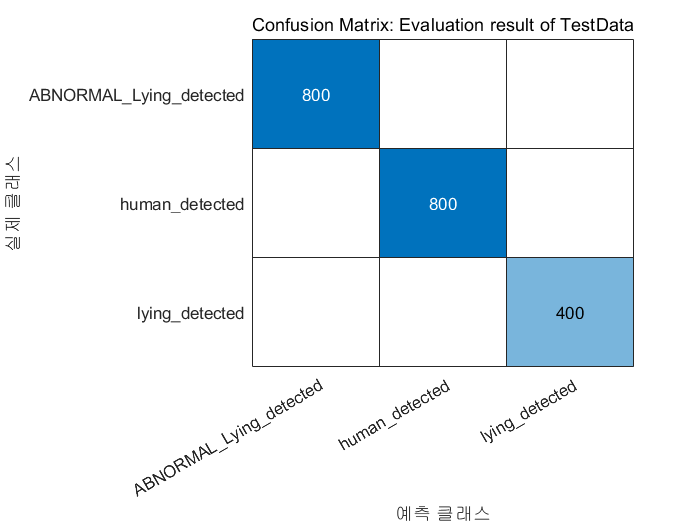

TestData_predict  = predict(Decision_Tree.Tree_Mdl, TestData_Table);

for idx = 1:length(TestData_predict);
    if string(TestData_predict(idx)) == 'lying_detected'
        coordinate_x = GT_LABEL{idx}(1);
        coordinate_y = GT_LABEL{idx}(2);
        if not (coordinate_x > min_bed_x & coordinate_x < max_bed_x) & (coordinate_y > min_bed_y & coordinate_y < max_bed_y)
            TestData_predict(idx) = {'ABNORMAL_Lying_detected'};
        end
    end
end

TestData_predict = categorical(TestData_predict);  % 예측한 값
TestData_Label   = categorical(NEW_LABEL.label);   % 실제 값

fig              = figure;
cm_post          = confusionchart(TestData_Label, TestData_predict);
cm_post.Title    = 'Confusion Matrix: Evaluation result of TestData';

[Table, sub_Table] = Evaluation_ConfMat(cm_post)

Table = 4×1 table
                 Evaluation Result
                 _________________

    Accuracy             1        
    Precision            1        
    Recall               1        
    F1_score             1        


sub_Table = 3×3 table
    Precision by Class    Recall by Class       F1scores by Class 
    __________________    __________________    __________________

            1                     1                     1         
            1                     1                     1         
            1                     1                     1         


# **5-1. PCA**

### Apply PCA

rng(0)

TrainData_Table_Array = table2array(TrainData_Table);
[PCA_coeff, PCA_data, ~, ~, PCA_explained, PCA_Center] = pca(TrainData_Table_Array);

% Returns Explained, the percentage of the total variance explained by each principal component
PCA_explained

PCA_explained =    72.6331
   25.6450
    1.3858
    0.3361


# **6.   Result & Conclusion**